# Digital Image Processing Assignment 1

## Student Name & Z Number: Meghananjali Remala, Z23701551

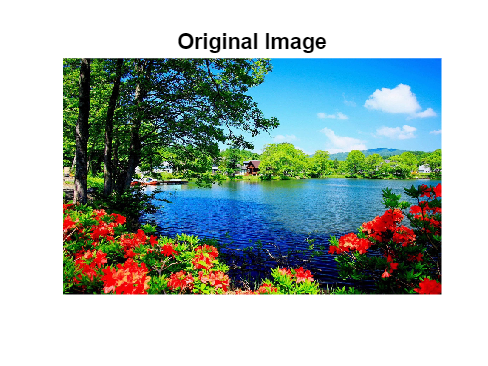

%% reading an image
creativeImgPath = 'DIP Assignment 1/Image.jpg';  
originalImg = imread(creativeImgPath);

%% displaying the image
figure('Name', 'Original Image');
imshow(originalImg);
title('Original Image');

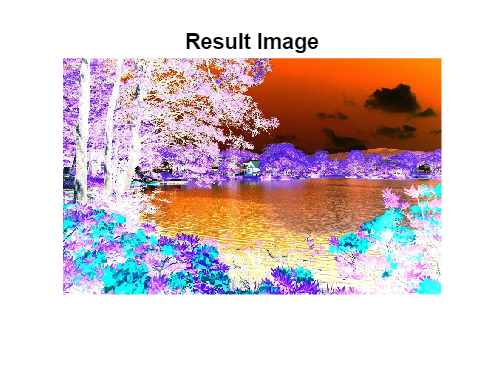


% select filter to be applied
filterChoice = questdlg('Select an Image Processing Filter:', 'Filter Select', 'Grayscale', 'Custom Filter', 'Grayscale');
if strcmp(filterChoice, 'Grayscale')
    processedImg = rgb2gray(originalImg);
else
    % Custom Filter: Invert Colors
    processedImg = imcomplement(originalImg);
end

%% displaying the result image
figure('Name', 'Result Image');
imshow(processedImg);
title('Result Image');


%% saving the resulting image
imwrite(processedImg, 'DIP Assignment 1/result_Image.png');
disp('Result image saved as result_Image.png');

Result image saved as result_Image.png
